# **Motion Planning with RRT for Fixed-Wing UAV **

This example demonstrates motion planning of a fixed-wing unmanned aerial vehicle (UAV) using the rapidly exploring random tree (RRT) algorithm given a start and goal pose on a 3-D map. A fixed-wing UAV is nonholonomic in nature, and must obey aerodynamic constraints like maximum roll angle, flight path angle, and airspeed when moving between waypoints.

In this example you will set up a 3-D map, provide the start pose and goal pose, plan a path with RRT using 3-D Dubins motion primitives, smooth the obtained path, and simulate the flight of the UAV.

% Set RNG seed for repeatable result  
clc;
clear all;
rng(1,"twister");

### Load Map

Load the 3-D occupancy map `uavMapCityBlock.mat`, which contains a set of pregenerated obstacles, into the workspace. The occupancy map is in an ENU (East-North-Up) frame.

mapData = load("uavMapCityBlock.mat","omap");
omap = mapData.omap;
% Consider unknown spaces to be unoccupied
omap.FreeThreshold = omap.OccupiedThreshold;

Using the map for reference, select an unoccupied start pose and goal pose.

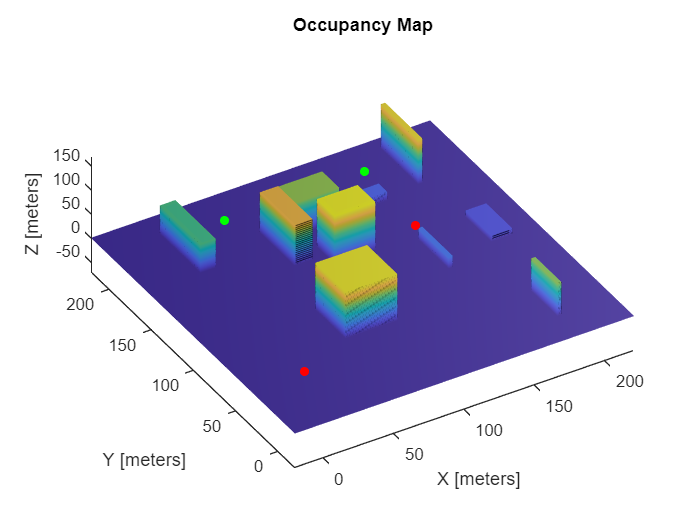

Astart = [12 22 25 pi];
Agoal = [150 180 35 pi];

Bstart = [150 120 25 0];
Bgoal = [50 180 35 pi/2];

figure("Name","StartAndGoal")
hMap = show(omap);
hold on
scatter3(hMap,Astart(1),Astart(2),Astart(3),30,"red","filled")
scatter3(hMap,Agoal(1),Agoal(2),Agoal(3),30,"green","filled")

scatter3(hMap,Bstart(1),Bstart(2),Bstart(3),30,"red","filled")
scatter3(hMap,Bgoal(1),Bgoal(2),Bgoal(3),30,"green","filled")

hold off
view([-31 63])

### Plan a Path with RRT Using 3-D Dubins Motion Primitives

RRT is a tree-based motion planner that builds a search tree incrementally from random samples of a given state space. The tree eventually spans the search space and connects the start state and the goal state. Connect the two states using a [`uavDubinsConnection`](docid:uav_ref#object_uavdubinsconnection) object that satisfies aerodynamic constraints. Use the `validatorOccupancyMap3D` object for collision checking between the fixed-wing UAV and the environment.

#### Define the State Space Object

This example provides a predefined state space, `ExampleHelperUavStateSpace`, for path planning. The state space is defined as `[x y z headingAngle]`, where `[x y z]` specifies the position of the UAV and `headingAngle` specifies the heading angle in radians. The example uses a [uavDubinsConnection](docid:uav_ref#object_uavdubinsconnection) object as the kinematic model for the UAV, which is constrained by maximum roll angle, airspeed, and flight path angle. Create the state space object by specifying the maximum roll angle, airspeed, and flight path angle limits properties of the UAV as name-value pairs. Use the `"Bounds"` name-value pair argument to specify the position and orientation boundaries of the UAV as a 4-by-2 matrix, where the first three rows represent the `x`-, `y`-, and `z`-axis boundaries inside the 3-D occupancy map and the last row represents the heading angle in the range `[-pi, pi]` radians. 

ss = ExampleHelperUAVStateSpace("MaxRollAngle",pi/6,...
                                "AirSpeed",6,... 
                                "FlightPathAngleLimit",[-0.1 0.1],...
                                "Bounds",[-20 220; -20 220; 10 100; -pi pi]);

Set the threshold bounds of the workspace based on the target goal pose. This threshold dictates how large the target workspace goal region around the goal pose is, which is used for bias sampling of the workspace goal region approach.

threshold = [(Agoal-0.5)' (Agoal+0.5)'; -pi pi];
% threshold2 = [(Bgoal-0.5)' (Bgoal+0.5)'; -pi pi];

Use the `setWorkspaceGoalRegion` function to update the goal pose and the region around it.

setWorkspaceGoalRegion(ss,Agoal,threshold)
% setWorkspaceGoalRegion(ss,Bgoal,threshold2)

#### Define the State Validator Object

The `validatorOccupancyMap3D` object determines that a state is invalid if the *xyz*-location is occupied on the map. A motion between two states is valid only if all intermediate states are valid, which means the UAV does not pass through any occupied location on the map. Create a `validatorOccupancyMap3D` object by specifying the state space object and the inflated map. Then set the validation distance, in meters, for interpolating between states.

sv = validatorOccupancyMap3D(ss,"Map",omap);
sv.ValidationDistance = 0.1;

#### Set Up the RRT Path Planner

Create a `plannerRRT` object by specifying the state space and state validator as inputs. Set the `MaxConnectionDistance`, `GoalBias`, and `MaxIterations` properties of the planner object, and then specify a custom goal function. This goal function determines that a path has reached the goal if the Euclidean distance to the target is below a threshold of 5 m.

planner = plannerRRT(ss,sv);
planner.MaxConnectionDistance = 50;  
planner.GoalBias = 0.10;  
planner.MaxIterations = 1000;
planner.GoalReachedFcn = @(~,x,y)(norm(x(1:3)-y(1:3)) < 5);

#### Execute Path Planning

Perform RRT-based path planning in 3-D space. The planner finds a path that is collision-free and suitable for fixed-wing flight.

rng default

% planning initially for agent A  
[pthObjA, solnInfoA] = plan(planner,Astart,Agoal);

% save all the nodes in a array for agent A  
NodesA=pthObjA.States;

% x=NodesA(1,2);
ss2 = ExampleHelperUAVStateSpace("MaxRollAngle",pi/6,...
                                "AirSpeed",6,...
                                "FlightPathAngleLimit",[-0.1 0.1],...
                                "Bounds",[-20 220; -20 220; 10 100; -pi pi]);

threshold2 = [(Bgoal-0.5)' (Bgoal+0.5)'; -pi pi];

setWorkspaceGoalRegion(ss2,Bgoal,threshold2)

sv2= validatorOccupancyMap3D(ss2,"Map",omap);
sv2.ValidationDistance = 0.1;

planner2 = plannerRRT(ss2,sv2);
planner2.MaxConnectionDistance = 50;
planner2.GoalBias = 0.10;  
planner2.MaxIterations = 1000;
planner2.GoalReachedFcn = @(~,x,y)(norm(x(1:3)-y(1:3)) < 5);


% planning initially for agent B
[pthObjB, solnInfoB] = plan(planner2,Bstart,Bgoal);

% % save all the nodes in a array for agent B
NodesB=pthObjB.States;

reached=0;

if (solnInfoA.IsPathFound) || (solnInfoB.IsPathFound)
    figure("Name","smoothedPath")


    
    allstatesA=[];
    allstatesB=[];
    


% reached=1 -----> A reached the goal position first
% reached=2 -----> B reached the goal position first 

    nodescount=numel(NodesB(:,1)); 
    %       Clear the current figure
        clf;
    for n=1:nodescount-1

        
        if n==numel(NodesA(:,1)) 
            reached=1;
        elseif n==numel(NodesB(:,1))
            reached=2;
        end
%         disp("n value=")
%         disp(n);
        %%%%%%%%%%%%%%%%%%% updating the paths %%%%%%%%%%%%%%%%%%%%
        statusA=1;
        statusB=0;

%         disp("A moves, B stops")

        [finalpathA, solutionA]= interplanner(n,NodesA,NodesB,statusA,statusB,reached);
            

      
        statusA=0;
        statusB=1;
           
%         disp("B moves, A stops")

        [finalpathB, solutionB]= interplanner(n,NodesA,NodesB,statusA,statusB,reached);
      
        %%%%%%%%%%%%%%%%%%% updating the paths %%%%%%%%%%%%%%%%%%%%

        %%%%%%%% animating the paths %%%%%%%%%

        %%%%%%%% Store the states for plotting %%%%%%%%

        allstatesA = [allstatesA; finalpathA.States];
        allstatesB = [allstatesB; finalpathB.States];


 

    end

end

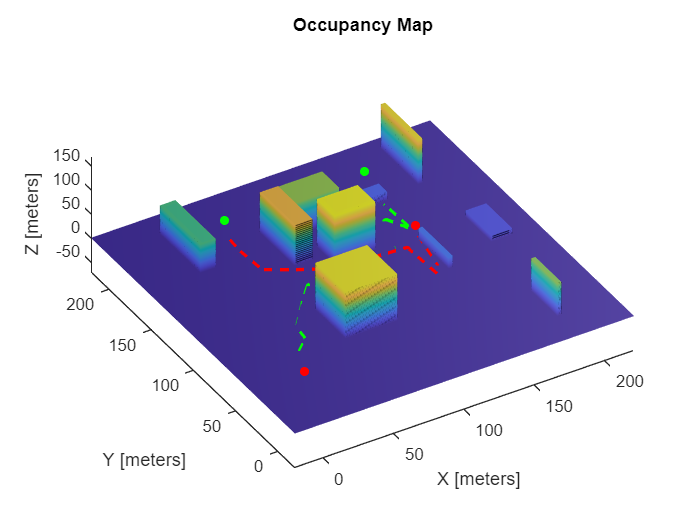

    show(omap)
    hold on
    scatter3(Bstart(1),Bstart(2),Bstart(3),30,"red","filled")
        scatter3(Bgoal(1),Bgoal(2),Bgoal(3),30,"green","filled")
    
    
    plot(allstatesB(:,1), allstatesB(:,2),"LineWidth", 5,"Color","r", "LineStyle",":");
    

    scatter3(Astart(1),Astart(2),Astart(3),30,"red","filled")
        scatter3(Agoal(1),Agoal(2),Agoal(3),30,"green","filled")
    
    
    plot(allstatesA(:,1), allstatesA(:,2),"LineWidth", 5,"Color","g", "LineStyle",":");
%     legend([hReference,hSimulated],"Reference","Simulated","Location","best")
    hold off
    view([-31 63])

## References

[1] Beard, Randal W., and Timothy W. McLain. *Small Unmanned Aircraft: Theory and Practice*. Princeton, N.J: Princeton University Press, 2012.

[2] Hornung, Armin, Kai M. Wurm, Maren Bennewitz, Cyrill Stachniss, and  Wolfram Burgard. “OctoMap: An Efficient Probabilistic 3D Mapping  Framework Based on Octrees.” *Autonomous Robots* 34, no. 3 (April 2013): 189–206. [https://doi.org/10.1007/s10514-012-9321-0](https://doi.org/10.1007/s10514-012-9321-0).

*Copyright 2020 The MathWorks, Inc.*